% ----------------------------------------------
% Generating Epsilon-Delta curves
% last updated: 06/10/2022
% ----------------------------------------------
% First, we obtaining discrete distribution pair (po,qo)
% The method used here are: 
% FFT-Fei, FFT-Gopi, Saddlepoint Accountant, Moments Accountant.
% ----------------------------------------------

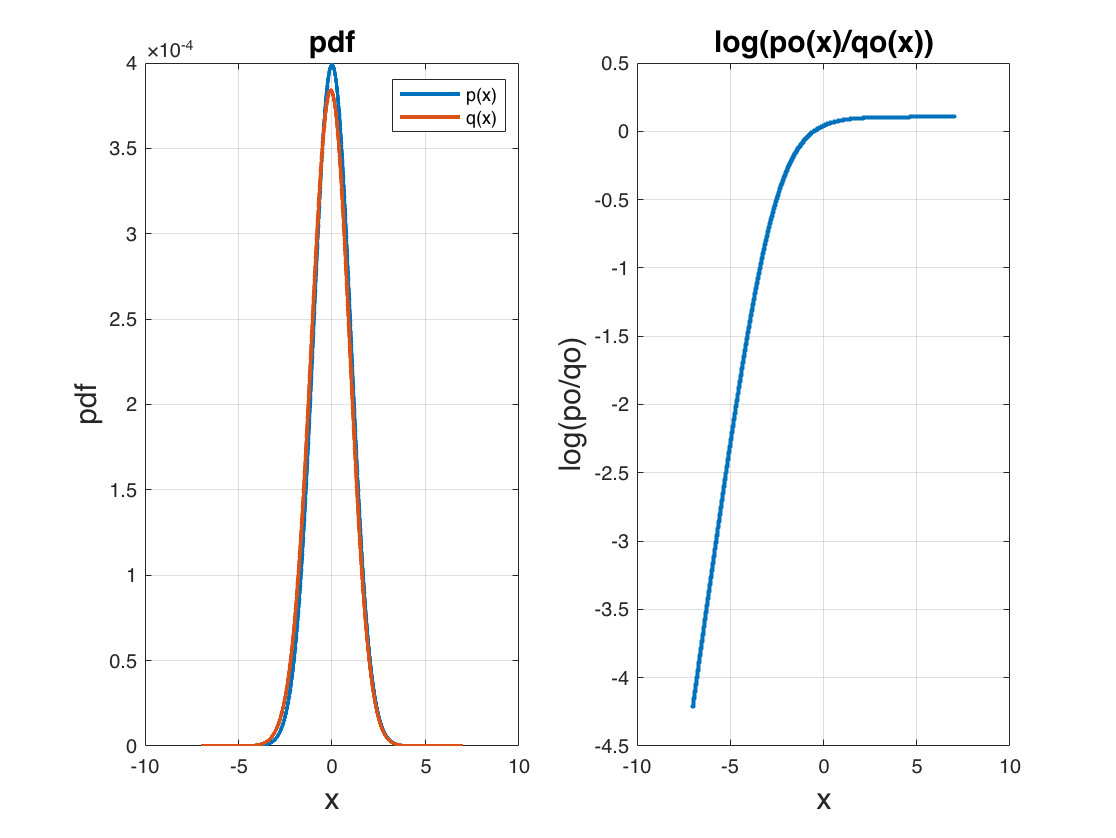

clear
close all

% let the show begin!
% note that for a single composition, we can compute the Egamma directly.

composition = 500;
sen = 1;
subsampling = 0.1;
sigma=sqrt(1);
noise_type=1;

switch noise_type
    case 0
        load(sprintf("cactusM_s%.1f_L2=%.2f.mat",sen,sigma^2))
        x_grid=x(1:end-sen*n);
        x_max=max(x_grid);
        po=p(1:end-sen*n);
        qo= subsampling*p(sen*n+1:end)+(1-subsampling)*po;
    otherwise
        % guassian
        if noise_type==1
            f = @(x) 1/sqrt(2*pi)/sigma*exp(-1/2*x.^2/sigma^2);

            pq = @(x)1./(1-subsampling+subsampling.*exp(-1/2/sigma^2*(2*x+1)));
        else
            % laplace
            b=sigma/sqrt(2);
            f = @(x) 1/2/b*exp(-abs(x)/b);
        end
        % Take samples, and its shift/subsampled.
        x_max = sigma*7;
        x_step_size = 1e-3;
        n = 1/x_step_size;
        x_grid = -x_max:x_step_size:x_max;
        po = f(x_grid)*x_step_size;
        qo = subsampling*f(x_grid+sen)*x_step_size+(1-subsampling)*po;
        po=po';
        qo=qo';

        pq_list=pq(x_grid)';

end

% this right here is a hack! This code is not properly accounting for the tails of the distribution
% po = po/(sum(po));
% qo = qo/(sum(qo));

KL=sum(po.*log(po./qo));

figure
subplot(1,2,1);
plot(x_grid,po,"LineWidth",2,'DisplayName','p(x)')
hold on
plot(x_grid,qo,"LineWidth",2,'DisplayName','q(x)')
xlabel('x','FontSize',15)
ylabel('pdf','FontSize',15)
title('pdf','FontSize',15)
legend;
grid on

subplot(1,2,2);
plot(x_grid,log(po./qo),'.',"LineWidth",2)
xlabel('x','FontSize',15)
ylabel('log(po/qo)','FontSize',15)
title('log(po(x)/qo(x))','FontSize',15)
grid on


Eg=@(gamma) sum(max(0,po-gamma*qo));
% Eg=@(gamma) sum(x_step_size*po.*max(0,1-gamma./pq_list));
% Eg = @(gamma) 1/2*(erfc((-1+2*sigma^2*log(gamma))/2/sqrt(2)/sigma)-...
%     gamma*erfc((1+2*sigma^2*log(gamma))/2/sqrt(2)/sigma));


% Next, we sample the Egamma curve uniformly.
if noise_type==1
    
    if subsampling~=1
        rate=po./qo;
        gamma_max=max(rate);
        gamma_min=min(rate);
    else
        gamma_max=min(10,exp(composition*KL*3));
    end
else
    rate=po./qo;
%     gamma_max=max(rate(1:end-n*sen));
    gamma_max=max(rate);
    gamma_min=min(rate);
end

l_step_size=1e-4;
l_grid=log(gamma_min):l_step_size:log(gamma_max);

% Now we consider Gopi's FFT approach, start with Gaussian mech.

if noise_type~=1
    disp('Warning: This method only works for subsampled Gaussian mechanism!')
end

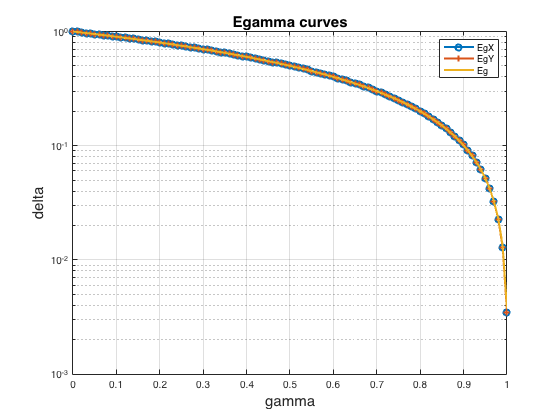


% Algorithm 2 (DiscretizePRV), 

f_x = @(x) 1/sqrt(2*pi)/sigma*exp(-1/2*x.^2/sigma^2);
Lxy= @(l) -(2*sigma^2*log(1/exp(l)/subsampling-1/subsampling+1)+sen^2)/2/sen;
f_l = @(l) f_x(Lxy(l))*sigma^2/sen/(1-(1-subsampling)*exp(l));

fLAnalytic_array1 =arrayfun(f_l,l_grid)*l_step_size;
fLAnalytic_array1=fLAnalytic_array1/sum(fLAnalytic_array1);

f_y = @(t) (1-subsampling)*f_x(t)+...
    subsampling*f_x(t+sen);
f_lGopiX = @(l) -f_y(-Lxy(l))*sigma^2/sen/(1-(1-subsampling)*exp(l));

fLAnalytic_array2 =arrayfun(f_lGopiX,l_grid)*l_step_size;
fLAnalytic_array2=fLAnalytic_array2/sum(fLAnalytic_array2);

EgX = @(gamma) sum(fLAnalytic_array1.*max(0,1-exp(log(gamma)-l_grid)));
EgY = @(gamma) sum(fLAnalytic_array2.*max(0,1-exp(log(gamma)-l_grid)));

figure

gamma_test0=0:1e-2:gamma_max*1.2;

semilogy(gamma_test0,arrayfun(EgX,gamma_test0),'-o',...
    'LineWidth',2,'DisplayName','EgX');
hold on

semilogy(gamma_test0,arrayfun(EgY,gamma_test0),'-+',...
    'LineWidth',2,'DisplayName','EgY');
hold on

semilogy(gamma_test0,arrayfun(Eg,gamma_test0),'-',...
    'LineWidth',2,'DisplayName','Eg');
legend;
xlabel('gamma','FontSize',15)
ylabel('delta','FontSize',15)
title('Egamma curves','FontSize',15)
grid on

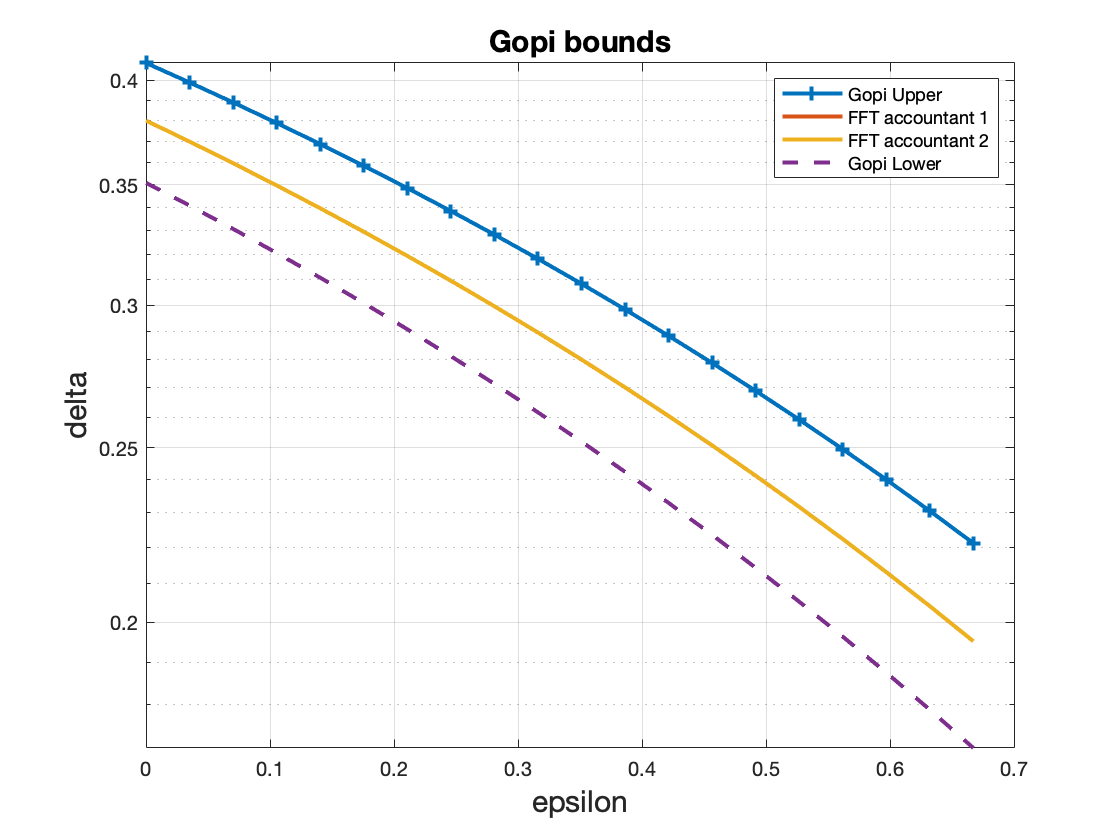

[l_grid_padding,fLConvFFT_array1]=fft_ConvN(l_grid,fLAnalytic_array1, composition);
% the Gopi's FFT bounds are given as follows.
delta_err_rate=1e-3;
eps_err = 0.1;
delta_GopiFFT_bd1 = @(eps) sum(fLConvFFT_array1.*max(0,1-exp(eps-l_grid_padding)));
delta_GopiFFT_upper = @(eps) delta_GopiFFT_bd1(eps-eps_err)*(1+delta_err_rate);
delta_GopiFFT_lower = @(eps) delta_GopiFFT_bd1(eps+eps_err)*(1-delta_err_rate);

[l_grid_padding,fLConvFFT_array2]=fft_ConvN(l_grid,fLAnalytic_array2, composition);
delta_GopiFFT_bd2 = @(eps) sum(fLConvFFT_array2.*max(0,1-exp(eps-l_grid_padding)));


figure

eps_grid=linspace(0,3*composition*KL,20);

delta_GopiFFT_upper_array = arrayfun(delta_GopiFFT_upper,eps_grid);
semilogy(eps_grid,delta_GopiFFT_upper_array,'-+',...
    "LineWidth",2,'DisplayName','Gopi Upper')
hold on

delta_GopiFFT_bd_array = arrayfun(delta_GopiFFT_bd1,eps_grid);
semilogy(eps_grid,delta_GopiFFT_bd_array,'-',...
    "LineWidth",2,'DisplayName','FFT accountant 1');
hold on

delta_GopiFFT_bd_array = arrayfun(delta_GopiFFT_bd2,eps_grid);
semilogy(eps_grid,delta_GopiFFT_bd_array,'-',...
    "LineWidth",2,'DisplayName','FFT accountant 2');
hold on

delta_GopiFFT_lower_array = arrayfun(delta_GopiFFT_lower,eps_grid);
semilogy(eps_grid,delta_GopiFFT_lower_array,'--',...
    "LineWidth",2,'DisplayName','Gopi Lower');

xlabel('epsilon','FontSize',15)
ylabel('delta','FontSize',15)
title('Gopi bounds','FontSize',15)
legend
grid on

% ----------------------------------------------
% FFT-Fei:
% ----------------------------------------------
% Step 1: Obtain a E-gamma curve on gamma_grid via function Eg(gamma_grid) -> Eg_grid
%
% Step 2(a): Obtain distribution pair upper bounding Eg_grid -> (p2,q2)
%       (b): Use (eps_grid,p2) as a random variable L_low 
%       (c): Perform FFT and iFFT to get convoluted (l_grid_padding,fLConvFFT_array2)
%       (d): Compute the Egamma_upper()
%
% Step 3(a): Obtain distribution pair lower bounding Eg_grid -> (p3,q3)
%       (b): Use (eps_grid,p3) as a random variable L_low 
%       (c): Perform FFT and iFFT to get convoluted (l_grid_padding,fLConvFFT_array3)
%       (d): Compute the Egamma_lower()
% ----------------------------------------------


% % Step Test
% gamma_step=(gamma_max-gamma_min)/1e4;
% gamma_grid=gamma_min:gamma_step:gamma_max;
% Eg_grid = arrayfun(Eg,gamma_grid); % samples uniform on Egamma curve
% Eg_grid = [Eg_grid,Eg_grid(end)];
% 
% % q is the sencond order derivative 
% % we didn't divide gamma_step twice as this is discrete!
% q1 = diff(Eg_grid,2)/gamma_step; 
% p1 = q1.* gamma_grid(2:end); % p is propotional to q
% q1=[q1,0];
% p1=[p1,1-sum(p1)];
% p1=[p1,0];
% q1=[q1,1-sum(q1)];
% 
% % We use Egamma1 for verifing the result.
% Egamma1 = @(gamma) sum(max(0,p1-gamma*q1));


% Now, instead of sample evenly on gamma, we sample uniformly on epsilon = log(gamma)
% Few things to note:
% (1) For gamma starts from 0, epsilon starts from some negetive value.
% (2) Since the sample is even on log(gamma), we also need dynamic step
% size on gamma. As the samples are dense on the left and loose on the
% right.

gamma_grid2 = exp(l_grid); % convert it to gamma, now the gamma samples are uniform on log

% Again, we use Egamma2 for verifing the result, it should be an upper bound of the true Egamma curve.
[p2,q2] = pq_upper(Eg,gamma_grid2);

% Lastly, we get a lower bounding discrete model (p3,q3).
Egslope = @(gamma) -sum(qo(po>gamma*qo));
[p3,q3] = pq_lower(Eg,Egslope,gamma_grid2);


figure
gamma_test2 = 0:1e-2:gamma_max*1.1;
semilogy(gamma_test2,arrayfun(Eg,gamma_test2),...
    "LineWidth",2,"DisplayName","Egamma");
hold on

% Eg_array_upper1 = arrayfun(Egamma1,gamma_grid_test);
% semilogy(gamma_grid2,Eg_array_upper1,'--D',...
%     "LineWidth",1.5,'DisplayName','EgammaUpper-gamma',...
%     'MarkerIndices',1:ceil(length(gamma_grid_test)/20):length(gamma_grid_test));
% hold on

Egamma_upper = @(gamma) sum(max(0,p2-gamma*q2));
Eg_array_upper2 = arrayfun(Egamma_upper,gamma_test2);
semilogy(gamma_test2,Eg_array_upper2,'--',...
    "LineWidth",1.5,'DisplayName','Egamma Upper Bound');
hold on

Egamma_lower = @(gamma) sum(max(0,p3-gamma*q3));
Eg_array_lower = arrayfun(Egamma_lower,gamma_test2);
semilogy(gamma_test2,Eg_array_lower,'-.',...
    "LineWidth",1.5,'DisplayName','Egamma Lower Bound');

xlabel("gamma",'FontSize',15);
ylabel("delta",'FontSize',15);
legend('FontSize',15)
grid on

% Step 2

% There's a minor problem with the upper bounding model, since the last value has q2(end)=0 but
% p2(end)>0. This correspondings to an infinite value of L, which doesn't show up in the grid.
% We can deal with this by slicing off the last value, then adding back to delta the probability 
% that any of the compositions happens to hit the last value. This occurs with probability
% 1-(1-p2(end))^composition
[l_grid_padding,fLConvFFT_array2] = fft_ConvN(l_grid,p2(2:end-1),composition);
delta_FFT_upper_bd = @(eps) sum(fLConvFFT_array2.*max(0,1-exp(eps-l_grid_padding)))+(1-(1-p2(end))^composition);

% Step 3

% We can actually avoid all FFT shifting (and normalization) if we zero-pad at the end of 
% the vector, rather than on both sides. In fact the fft function will automatically do this
% if we just add a second argument with the desired length
[l_grid_padding,fLConvFFT_array3] = fft_ConvN(l_grid,p3,composition);
delta_FFT_lower_bd = @(eps) sum(fLConvFFT_array3.*max(0,1-exp(eps-l_grid_padding)));


figure
plot(l_grid_padding,abs(fLConvFFT_array2)/l_step_size,'-.',...
    'LineWidth',2,'DisplayName','upper bd');
hold on
plot(l_grid_padding,abs(fLConvFFT_array3)/l_step_size,'-.',...
    'LineWidth',2,'DisplayName','lower bd');
legend;
xlabel('l','FontSize',15)
ylabel('pdf','FontSize',15)
title(sprintf('composition = %d',composition),'FontSize',15)
grid on

% The whole idea here is the following: we first derive the approximate
% (P,Q) pair which has the same E-gamma curve but also has nice bijictive
% properties that leads to the (approximate) privacy loss random variable,
% then we are ready to apply the FFT to compute the convoluted pdf to deal
% with compositions.


% Here we setup the grids for testing.
% eps_max_test=composition*KL*20;
eps_max_test=5*composition*KL;
eps_grid_test = linspace(1e-10,eps_max_test,20);


% With FFT delta curve as a baseline, now we derive the saddle-point
% curves. Basically there are two approaches, one is directly from the
% orignal noise distributions, one is from the convoluted pdf (FFT).

a_max=10;
a_min=1e-5;

fL_array = p2(2:end-1);

EexptL=@(t) sum(fL_array.*exp(t*l_grid));

fLTilt=@(t) exp(t*l_grid).*fL_array/EexptL(t);

K = @(t,n) n*log(EexptL(t));
K1 = @(t,n) n*sum(fL_array.*l_grid.*exp(t*l_grid))./EexptL(t);
K2 = @(t,n) n*(sum(fL_array.*l_grid.^2.*exp(t*l_grid))./EexptL(t)-K1(t,1).^2);

gmax= @(t) t.^t./(t+1).^(t+1);

C=6;
ELTilt = @(t) sum(l_grid.*fLTilt(t));
T = @(t,n) sum(fLTilt(t).*abs(l_grid-ELTilt(t)).^3)*n;

delta27 = @(eps,t,n) exp(K(t,n)-eps*t)*(1/sqrt(2*pi*K2(t,n))/t/(t+1));
error = @(t,n) 2*gmax(t)*T(t,n)*t*(t+1)/K2(t,n)*C;

t_list=zeros(length(eps_grid_test),1);
for i =1:length(eps_grid_test)
    tic
    t_list(i)=fminbnd(@(t) delta27(eps_grid_test(i),t,composition).*(1+error(t,composition)),a_min,a_max);
    toc
end

Elapsed time is 0.070421 seconds.
Elapsed time is 0.030754 seconds.
Elapsed time is 0.027968 seconds.
Elapsed time is 0.025883 seconds.
Elapsed time is 0.039444 seconds.
Elapsed time is 0.020438 seconds.
Elapsed time is 0.021860 seconds.
Elapsed time is 0.023469 seconds.
Elapsed time is 0.023184 seconds.
Elapsed time is 0.021706 seconds.
Elapsed time is 0.021400 seconds.
Elapsed time is 0.024158 seconds.
Elapsed time is 0.025071 seconds.
Elapsed time is 0.024251 seconds.
Elapsed time is 0.030406 seconds.
Elapsed time is 0.026194 seconds.
Elapsed time is 0.027508 seconds.
Elapsed time is 0.056541 seconds.
Elapsed time is 0.051153 seconds.
Elapsed time is 0.051699 seconds.



delta_27=zeros(length(eps_grid_test),1);
for i = 1:length(eps_grid_test)
    delta_27(i)=delta27(eps_grid_test(i),t_list(i),composition);
end
error_array=arrayfun(@(t) error(t,composition),t_list);

% Alternative, we can directly compute the K functions with original
% distributions.
% 
% ps=po;
% qs=qo;
% 
% mgf = @(t) sum(ps.*(ps./(qs+1e-20)).^t);
% logmgf = @(t) log(sum(ps.*(ps./(qs+1e-20)).^t));
% KB = @(t,n) n*logmgf(t);
% K1B = @(t,n) n*sum(ps.*log(ps./(qs+1e-20)).*(ps./(qs+1e-20)).^t)/mgf(t);
% K2B = @(t,n) n*(sum(ps.*(log(ps./(qs+1e-20))).^2.*(ps./(qs+1e-20)).^t)/mgf(t)-K1B(t,1).^2);
% 
% C=6;
% ELtilt3 = @(t) sum(ps.*(log(ps./(qs+1e-20))).^3.*(ps./(qs+1e-20)).^t)/mgf(t); %!!!
% TB = @(t,n) n*abs(ELtilt3(t)-(K1B(t,1)).^3-3*K1B(t,1).*K2B(t,1));
% 
% delta27B = @(eps,t,n) exp(KB(t,n)-eps*t)*(1/sqrt(2*pi*K2B(t,n))/t/(t+1));
% errorB = @(t,n) 2*gmax(t)*TB(t,n)*t*(t+1)/K2B(t,n)*C;
% 
% t_listB=zeros(length(eps_grid_test),1);
% for i =1:length(eps_grid_test)
%     tic
%     t_listB(i)=fminbnd(@(t) delta27B(eps_grid_test(i),t,composition).*(1+errorB(t,composition)), a_min,a_max);
%     toc
% end
% delta_27B=zeros(length(eps_grid_test),1);
% for i = 1:length(eps_grid_test)
%     delta_27B(i)=delta27B(eps_grid_test(i),t_listB(i),composition);
% end
% 
% error_arrayB=arrayfun(@(t) errorB(t,composition),t_listB);

a_grid= linspace(a_min,max(t_list),20);
figure;
plot(a_grid,arrayfun(@(t) K(t,composition),a_grid),"LineWidth",1.5,"DisplayName","K(t)");
hold on
plot(a_grid,arrayfun(@(t) K1(t,composition),a_grid),"LineWidth",1.5,"DisplayName","K'(t)");
hold on
plot(a_grid,arrayfun(@(t) K2(t,composition),a_grid),"LineWidth",1.5,"DisplayName","K''(t)");
% hold on
% plot(a_grid,arrayfun(@(t) KB(t,composition),a_grid),'--',"LineWidth",1.5,"DisplayName","K(t) Alt");
% hold on
% plot(a_grid,arrayfun(@(t) K1B(t,composition),a_grid),'--',"LineWidth",1.5,"DisplayName","K'(t) Alt");
% hold on
% plot(a_grid,arrayfun(@(t) K2B(t,composition),a_grid),'--',"LineWidth",1.5,"DisplayName","K''(t) Alt");

xlabel("t","FontSize",13)
title(sprintf('cgf with derivatives, compositions=%d',composition))
legend;
grid on


% Moments accountant
alpha_max = 50; %maximum lambda in MGF
alpha_grid =1.1:0.1:alpha_max;
rdp = ma_ComputeRDP(po,qo,alpha_grid);
delta_MA_array = zeros(length(eps_grid_test),1);
for i=1:length(eps_grid_test)
    eps = eps_grid_test(i);
    delta_MA_array(i) = ma_ComputeDelta(alpha_grid, composition*rdp,eps);
end

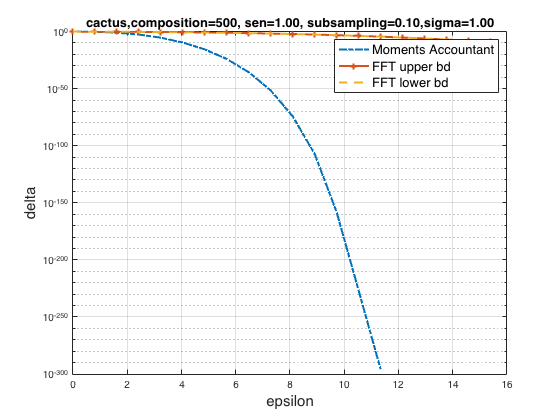


figure

semilogy(eps_grid_test,delta_MA_array,'-.',...
    "LineWidth",2,"DisplayName","Moments Accountant")
hold on

fft_upper = abs(arrayfun(delta_FFT_upper_bd,eps_grid_test));
semilogy(eps_grid_test,fft_upper,'-+',...
    "LineWidth",2,"DisplayName","FFT upper bd")
hold on


fft_lower = abs(arrayfun(delta_FFT_lower_bd,eps_grid_test));
semilogy(eps_grid_test,fft_lower,'--',...
    "LineWidth",2,"DisplayName","FFT lower bd")
hold on

% delta_GopiFFT_upper_array = arrayfun(delta_GopiFFT_upper,eps_grid_test);
% semilogy(eps_grid_test,delta_GopiFFT_upper_array,'-+',...
%     "LineWidth",2,'DisplayName','Gopi Upper')
% hold on

% delta_GopiFFT_bd_array = arrayfun(delta_GopiFFT_bd1,eps_grid_test);
% semilogy(eps_grid_test,delta_GopiFFT_bd_array,'-',...
%     "LineWidth",2,'DisplayName','Analytic FFT');
% hold on

% delta_GopiFFT_lower_array = arrayfun(delta_GopiFFT_lower,eps_grid_test);
% semilogy(eps_grid_test,delta_GopiFFT_lower_array,'--',...
%     "LineWidth",2,'DisplayName','Gopi Lower');


% semilogy(eps_grid_test,delta_27,'--D',...
%     "LineWidth",1.5,"DisplayName","Saddlepoint")
% hold on
% 
% semilogy(eps_grid_test,delta_27.*(1+error_array),'--D',...
%     "LineWidth",1.5,"DisplayName","Base Term with Error")
% hold on

noise_names=["cactus" "gaussian" "laplace"];
title(sprintf('%s,composition=%d, sen=%.2f, subsampling=%.2f,sigma=%.2f',...
    noise_names(noise_type+1),composition,sen,subsampling,sigma),'FontSize',13)
xlabel("epsilon",'FontSize',15)
ylabel('delta','FontSize',15)
legend('FontSize',13);
grid on